#   Lab session IV:

## Intro:

On this Laboratory session we are going to work with the different attitude representations seen in class. 

- Exercise 1: 1 point. To be delivered before the end of the session.

- Exercise 2: 3 points

- Exercise 3: 3 points

- Exercise 4: 3 points

**Lab rules:**

- Always respect the delivery dates

- Use the templates when provided and DO NOT MODIFY THE FILE NAMES OR THE FUNCTION NAMES

- Verify that your code works before submit

- Always upload the files in a .zip with the name structure:  * Surname_Name.zip*

- Cheating is not allowed and will be firmly punished with a final mark of 0

This assignment is due to 

# Exercise 1:

The point p has coordinates

p_A = [3, 4]';

on a frame {A}, and coordinates

p_B = [-2.5, 0.5]';

on a frame {B}.

It is known that the angle between $x$-axis of frame {A} and the$y$-axes of the frame {B} is 30 deg counterclockwise.

##  1.1 Which are the coordinates of the origin of A seen from B?

bRa = [cosd(60) -sind(60);sind(60) cosd(60)];
bDba = p_B - bRa * p_A

bDba =    -0.5359
   -4.0981


*The distance between frames {A} and {B} seen from the frame {A} is (-0.5359, -4.0981)'.*

##  1.2 Which are the coordinates of the origin of B seen from A?

aDab = -bRa' * bDba

aDab =     3.8170
    1.5849


*The distance between frames {A} and {B} seen from the frame {B} is (3.8170, 1.5849)'.*

##  1.3 Which are the coordinates of a point q expressed in A if 

q_B = [3,1]';
q_A = bRa' * q_B + aDab

q_A =     6.1830
   -0.5131


*The coordinates of a point Q expressed in {A} frame are Qa(6.1830,-0.5131).*

# Exercise 2:

 Let {A}, {B} and {C}, be 3 different reference frames. From them we know that:

- The origin of B with respect A is

AoB = [3,1,-2]';

- The origin of C with respect B is

BoC = [-3, 1,-2]';

- The three frames has different orientations in space. In fact:  

- The set of Euler angles stored in $\eta$ as $\eta = (\psi,\theta,\phi)$

eta = [25;145;30]; % Expressed in degrees

                 represent 3 consecutive rotations about z, y, and x respectively that allows to transform vectors from {A} to {B}

- The quaternion

q = 1/7*[-sqrt(3)*3.5;3;-1;-1.5];

                 allows to express in {B} a vector defined in {C}, if {C} and {B} had the same origin

Let in addition v1 and v2 to be points which coordinates are known in  {C}.

v1_C = [0;2;0];
v2_C = [0;2;5];

With the information provided above determine:

##  2.1.1 The affine** expression** that allows to relate a vector originally given in {C} to {B}. Note that no calculations have to be provided here, only the expression which is not a matrix.

- 
$$\overset{B}{p} =\overset{B}{\underset{C}{R\;}} \overset{C}{p} \;+\overset{B}{\underset{B\to C}{d}}$$


- $\overset{B}{\underset{C}{A}} =\left\lbrack \begin{array}{cc}
\overset{B}{\underset{C}{R}}  & \overset{B}{\underset{B\to C}{d}} \\
0_{1\textrm{X3}}  & 1
\end{array}\right\rbrack$*Multiplied by the given vector in {C}.*

## 2.1.2 Implement a function called rotVbyq that provided a vector and a quaternion rotates the vector using quaternion multiplications. Test it and commet why do you think it is well implemented.

qa = [cosd(30);sind(30)*[4/3;1/3;4/3]];
v = [1;2;3];
Rv = rotVbyq(v,qa)

Rv =     2.3900
   -1.6427
    5.5207


Rv1_C = rotVbyq(v1_C,q)

Rv1_C =    -0.9872
    1.0816
   -1.3622


Rv2_C = rotVbyq(v2_C,q)

Rv2_C =    -0.6684
    5.0993
    1.5970


*The function is well implemented because the function uses a pure quaternion created from the given vector "v". Also it uses a unit quaternion "q". As we want to rotate it 60 degrees, we create the initial quaternion by dividing the angle by 2 and inside the function the multiplication is made 2 times using the also the conjugated quaternion: *$\dot{\acute{v} } =\dot{q} \dot{v} \dot{\tilde{q} }$.

##  2.2 The affine matrix that allows to express a vector originally given in {C} to {A}.

bRa = eAngles2rotM(eta(1),eta(2),eta(3));
aRb = bRa';                               % We know the rotation matrix from {b} to {a}
AoC = AoB + aRb * BoC;                    % We know the distance between {a} to {c} from {a}
bRc = quaternion2Rmatrix(q);        
aRc = aRb * bRc;                          % We know the rotation matrix from {c} to {a}
aAc = aRc;
aAc(1:3,4) = AoC;
aAc(4,:) = [0 0 0 1]

aAc =    -0.2553    0.9859   -0.0206    6.7285
    0.1636    0.8459    0.5077    3.3281
    0.8674    0.1218   -0.4824   -2.6058
         0         0         0    1.0000


*The affine matrix to express a vector given in {C} in {A} is the one above.*

## 2.3 The vectors v1_C and v2_C forms a segment. Make a 3d plot (plot3() in matlab), representing how the segment is seen on {A} in red, on {B} in blue and on {C} in green.

*The next plot in 3 dimensions represents in an absolute frame. So in this same frame the changes (rotations and translations) between the frames {A}{B} & {C} will be seen.*

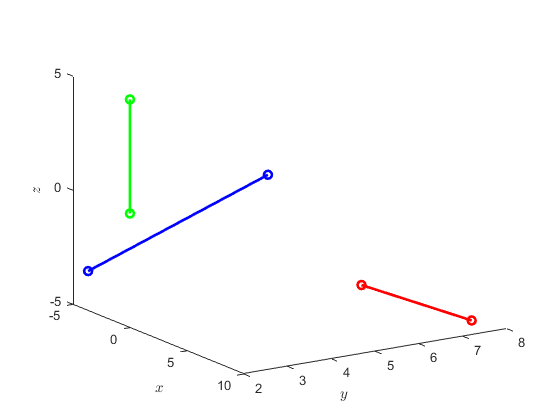

v1_C;                           % Vector points seen from frame {C}
v2_C;

v1_a = aAc * [v1_C;1];          % Vector points seen from frame {A}
v1_A = v1_a(1:3);
v2_a = aAc * [v2_C;1];
v2_A = v2_a(1:3);

bAc = bRc;                      % Affine matrix from frame {C} to frame {B}
bAc(1:3,4) = BoC;
bAc(4,:) = [0 0 0 1];

v1_b = bAc * [v1_C;1];          % Vector points seen from frame {B}
v1_B = v1_b(1:3);
v2_b = bAc * [v2_C;1];
v2_B = v2_b(1:3);

hold on;
plot3([v1_A(1);v2_A(1)],[v1_A(2);v2_A(2)],[v1_A(3);v2_A(3)],'Color',[1,0,0],'LineWidth',2);
plot3(v1_A(1),v1_A(2),v1_A(3),'Marker','o','Color',[1,0,0],'LineWidth',2);
plot3(v2_A(1),v2_A(2),v2_A(3),'Marker','o','Color',[1,0,0],'LineWidth',2);
plot3([v1_B(1);v2_B(1)],[v1_B(2);v2_B(2)],[v1_B(3);v2_B(3)],'Color',[0,0,1],'LineWidth',2);
plot3(v1_B(1),v1_B(2),v1_B(3),'Marker','o','Color',[0,0,1],'LineWidth',2);
plot3(v2_B(1),v2_B(2),v2_B(3),'Marker','o','Color',[0,0,1],'LineWidth',2);
plot3([v1_C(1);v2_C(1)],[v1_C(2);v2_C(2)],[v1_C(3);v2_C(3)],'Color',[0,1,0],'LineWidth',2);
plot3(v1_C(1),v1_C(2),v1_C(3),'Marker','o','Color',[0,1,0],'LineWidth',2);
plot3(v2_C(1),v2_C(2),v2_C(3),'Marker','o','Color',[0,1,0],'LineWidth',2);
view([57 20]);
xlabel('$x$','interpreter','Latex')
ylabel('$y$','interpreter','Latex')
zlabel('$z$','interpreter','Latex')
hold off;

# Exercise 3:

The points described by the columns of the matrix A 

A = load('AEx3.mat');
A = A.A;

are points contained into a circle, and they are defined in a world frame W.

A camera is situated at point

WoC = [1; 6; 1];

 defined in the world frame. Moreover the orientation of this camera frame is achieved by rotating the world frame 90 degs about its y axis followed by -20 degrees about the resulting z axis.

If the camera has a focal length of 1/34 m:

fl = 1/34;

##  3.1 Make a plot with the view of the points of the circle projected into the camera plane.

*Now on an affine matrix is used to transform all the points:*

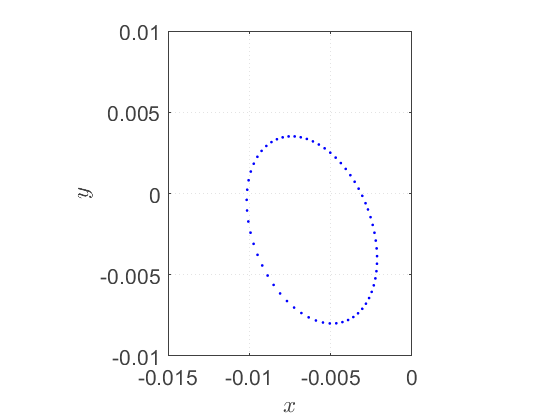

cRw = eAngles2rotM(-20,90,0);
cAw = [cRw -cRw*WoC; 0 0 0 1];
wAc = [cRw' WoC; 0 0 0 1];
[Pt] = cameraproj(cAw,fl,A);

figure1 = figure('Color',[1 1 1]);
PS=get(figure1,'PaperPosition');
PS(1)=0;
PS(2)=0;
PS(3)=PS(3)*.5;
PS(4)=PS(4)*.5;
set(figure1,'PaperPosition',PS);
% Create axes

axes1 = axes('Parent',figure1,...
    'YMinorGrid','off','YGrid','on',...
    'XMinorGrid','off','XGrid','on',...
    'ZMinorGrid','off','ZGrid','on',...
    'GridLineStyle',':','MinorGridLineStyle',':',...
    'XColor',[0.25,0.25,0.25],...
    'YColor',[0.25,0.25,0.25],...
    'xlim', [-0.015,0],...
    'ylim', [-0.01,0.01],...
    'DataAspectRatio',[1 1 1],...
    'FontSize',16);
box(axes1,'on');
hold(axes1,'on');
for i = 1 : 1 : 63
    plot(Pt(1,i),Pt(2,i),'Marker','.','Color',[0,0,1],'LineWidth',2);
end
hold(axes1,'off');
xlabel(axes1,'$x$','interpreter','Latex')
ylabel(axes1,'$y$','interpreter','Latex')

*The plot only shows the points and no lines because the exercise doesn't say so.*

##  3.2 Make also a 3D plot where all the scene is drawn in the world coordinates. The scene must contain the 2 reference frames (2 orthogonal sets of vectors) and the circle points. 

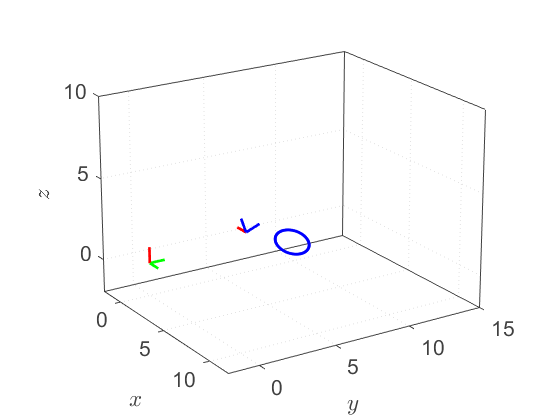

wo = [0;0;0];               % World frame center 
xw = [1;0;0];               % World frame triade vectors
yw = [0;1;0];
zw = [0;0;1];
wxc = wAc * [xw;1];         % Composing camera triade vectors
wxc = wxc(1:3);
wyc = wAc * [yw;1];
wyc = wyc(1:3);
wzc = wAc * [zw;1];
wzc = wzc(1:3);

% Plot functions
figure1 = figure('Color',[1 1 1]);
PS=get(figure1,'PaperPosition');
PS(1)=0;
PS(2)=0;
PS(3)=PS(3)*.5;
PS(4)=PS(4)*.5;
set(figure1,'PaperPosition',PS);
% Create axes

axes1 = axes('Parent',figure1,...
    'YMinorGrid','off','YGrid','on',...
    'XMinorGrid','off','XGrid','on',...
    'ZMinorGrid','off','ZGrid','on',...
    'GridLineStyle',':','MinorGridLineStyle',':',...
    'XColor',[0.25,0.25,0.25],...
    'YColor',[0.25,0.25,0.25],...
    'ZColor',[0.25,0.25,0.25],...
    'xlim', [-2,12],...
    'ylim', [-2,15],...
    'zlim', [-2,10],...
    'Projection','perspective',...
    'DataAspectRatio',[1 1 1],...
    'FontSize',16);
box(axes1,'on');
view(axes1,[57 20]);
hold(axes1,'on');

xlabel(axes1,'$x$','interpreter','Latex')
ylabel(axes1,'$y$','interpreter','Latex')
zlabel(axes1,'$z$','interpreter','Latex')

plot3([wo(1);xw(1)],[wo(2);xw(2)],[wo(3);xw(3)],'Color',[0,1,0],'LineWidth',2);
plot3([wo(1);yw(1)],[wo(2);yw(2)],[wo(3);yw(3)],'Color',[0,1,0],'LineWidth',2);
plot3([wo(1);zw(1)],[wo(2);zw(2)],[wo(3);zw(3)],'Color',[1,0,0],'LineWidth',2);
plot3([WoC(1);wxc(1)],[WoC(2);wxc(2)],[WoC(3);wxc(3)],'Color',[0,0,1],'LineWidth',2);
plot3([WoC(1);wyc(1)],[WoC(2);wyc(2)],[WoC(3);wyc(3)],'Color',[0,0,1],'LineWidth',2);
plot3([WoC(1);wzc(1)],[WoC(2);wzc(2)],[WoC(3);wzc(3)],'Color',[1,0,0],'LineWidth',2);

for i = 1 : 1 : 63
    plot3(A(1,i),A(2,i),A(3,i),'Marker','.','Color',[0,0,1],'LineWidth',2);
end

hold(axes1,'off');

You can use the provided function cameraproj.

# Exercise 4:

The columns of the next matrix, represents the coordinates od 4 points defined in a world frame.

A = load('AEx4.mat');
A = A.A;

From this 4 points, two segments are defined. The segment one, goes from the point defined by the first column to the point defined by the second column. The second segment is defined by the other two points.

 A camera frame is seeing the scene. The origin of the world frame seen from the camera frame is given by the vector

WoC = [4.665;3.735;-0.5395];

And the orientation of the camera frame is obtained after rotating the world frame -150 degs about the direction

u = [0.01;-.2;1];

With the data provided determine:

## 4.1 The minimum angle that both segments forms (hint, they intersect)

*If there is an angle between two segments it can be found just by using the scalar product. So:*

a = A(:,2)-A(:,1);
b = A(:,4)-A(:,3);
theta = acosd((a(1)*b(1)+a(2)*b(2)+a(3)*b(3))/(sqrt(a'*a)*sqrt(b'*b)))

theta = 53.1301

*So the minimum angle between both segments is theta = 53.1301 degrees.*

## 4.2 The angle that both segments forms in the image plane

## 4.3 Deliver a 3D representation of the scene with all the coordinates refered to the world frame

## 4.4 Deliver the same 3D scene representations but with all the coordinates refered to the camera frame